# Filter Design

## Introduction

**The goal of these exercises is to apply filtering principles to the following situation:**

**Given a real-valued signal **$x[n] \in \mathbb{R}$** (see top plot of figure 1) such that:**


$$x[n]=x_{target}[n]+w[n]$$


**where**


$$x_{target}[n]=\sin(2{\pi}0.06n)+\frac{1}{3}\sin(2{\pi}0.18n)+\frac{1}{5}\sin(2{\pi}0.3n)$$


**and**


$$w[n]=\sin(2{\pi}0.01n)+\frac{1}{2}\sin(2{\pi}0.4n)$$


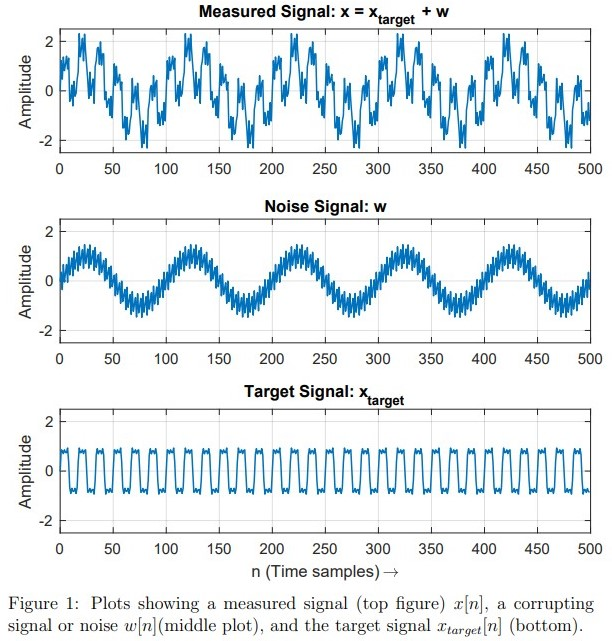

*Figure 2 shows the magnitude of the DTFT of x as a function of normalized frequency *$\omega$*. The portion of the magnitude spectrum that belongs to the target signal *$x_{target}$* is highlighted in red.*

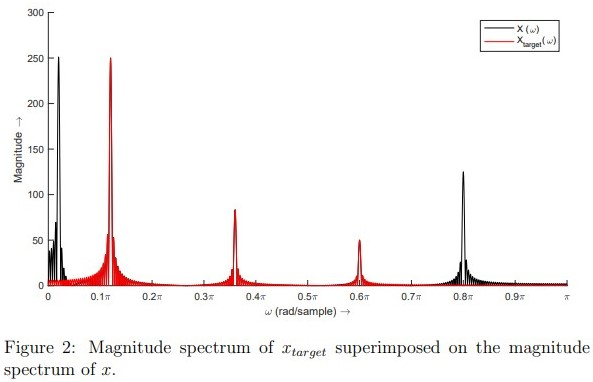

**The idea is to design a band-pass filter that allows to isolate xtarget from x, first by using an ideal band-pass filter, then by using an FIR filter designed by the means of the windowing method, and finally by using an IIR filter to perform the same task.**

## Part 1 – Ideal Filtering

The impulse response of an ideal band-pass filter with a passband starting at $\omega_{a}$ and ending at $\omega_b$ is computed by hand below. The impulse response should be real.

From $x_{target}$, there are 3 frequencies that compose this signal; $2\pi0.06$, $2\pi0.18$, $2\pi0.3$. The smallest of those frequencies is the $\omega_a=2\pi0.06$ and the largest is the $\omega_b=2\pi0.3$.


$$B(\omega)=\left\{\matrix{1 & if & \omega_a \leq |\omega| \leq \omega_b \cr 0 & otherwise}$$



$$b[n]=\frac{1}{2\pi}\int_{-\pi}^{\pi}{B(\omega)e^{j{\omega}n}d\omega}$$



$$b[n]=\frac{1}{2\pi}\int_{-\omega_b}^{-\omega_a}{B(\omega)e^{j{\omega}n}d\omega}+\frac{1}{2\pi}\int_{\omega_a}^{\omega_b}{B(\omega)e^{j{\omega}n}d\omega}$$



$$b[n]=\frac{1}{2\pi}\int_{-\omega_b}^{-\omega_a}{(1)e^{j{\omega}n}d\omega}+\frac{1}{2\pi}\int_{\omega_a}^{\omega_b}{(1)e^{j{\omega}n}d\omega}$$



$$b[n]=\frac{1}{2\pi} \left[ \frac{e^{j{\omega}n}}{jn} \right]_{\omega=-\omega_b}^{-\omega_a} +
\frac{1}{2\pi} \left[ \frac{e^{j{\omega}n}}{jn} \right]_{\omega=\omega_a}^{\omega_b}$$



$$b[n]=
\left( \frac{1}{2\pi} \right) \left( \frac{e^{-j{\omega_a}n}-e^{-j{\omega_b}n}}{jn} \right) + 
\left( \frac{1}{2\pi} \right) \left( \frac{e^{j{\omega_b}n}-e^{j{\omega_a}n}}{jn} \right) $$



$$b[n]=
 \frac{e^{j{\omega_b}n}-e^{-j{\omega_b}n}}{2jn\pi} - 
 \frac{e^{j{\omega_a}n}-e^{-j{\omega_a}n}}{2jn\pi}$$



$$b[n]=
 \frac{\sin(\omega_bn)}{n\pi} - 
 \frac{\sin(\omega_an)}{n\pi}$$



$$b[n]=
 \frac{\sin(\omega_bn)-\sin(\omega_an)}{n\pi} 
$$


Solving for $n=0$:


$$b[0]
= \lim_{n \rightarrow 0} \frac{\sin(\omega_bn)-\sin(\omega_an)}{n\pi} 
= \lim_{n \rightarrow 0} \frac{\omega_b\cos(\omega_bn)-\omega_a\cos(\omega_an)}{\pi} 
= \frac{\omega_b-\omega_a}{\pi}$$


**The time domain representation of this filter can be observed below:**

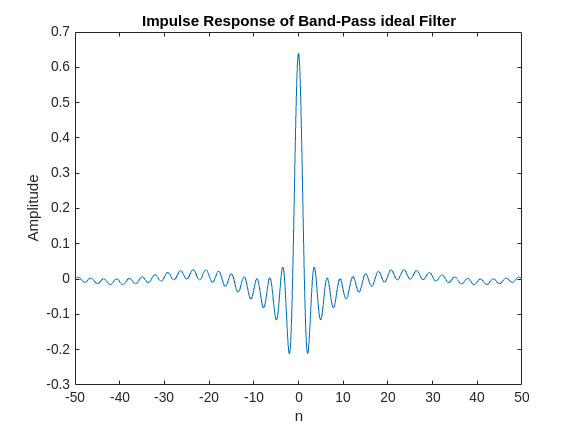

wa = 0.06 * pi;
wb = 0.7 * pi;

n = -50:0.01:50;

h_ideal = (sin(wb * n) - sin(wa * n)) ./ (pi * n);

figure;
plot(n, h_ideal);
title("Impulse Response of Band-Pass ideal Filter");
xlabel('n');
ylabel('Amplitude');

**Sources used to complete this section:**

- [https://www.youtube.com/watch?v=ii8ofk21StQ&ab_channel=Engg-Course-Made-Easy](https://www.youtube.com/watch?v=ii8ofk21StQ&ab_channel=Engg-Course-Made-Easy)

## Part 2 – FIR Filter Design 

### Step 1: Causal, Linear-Phase FIR Filter

In MATLAB®, a rectangular window (a rectangular signal) is used to turn this impulse response into a causal, linear-phase FIR filter $H_L$ of lengths:

- 
$$L=17$$


- 
$$L=33$$


- 
$$L=65$$


The impulse response is plotted for each case using MATLAB®, with $\omega_a= 0.06 \pi$ and $\omega_b = 0.7 \pi$.

#### 
$$L=17$$


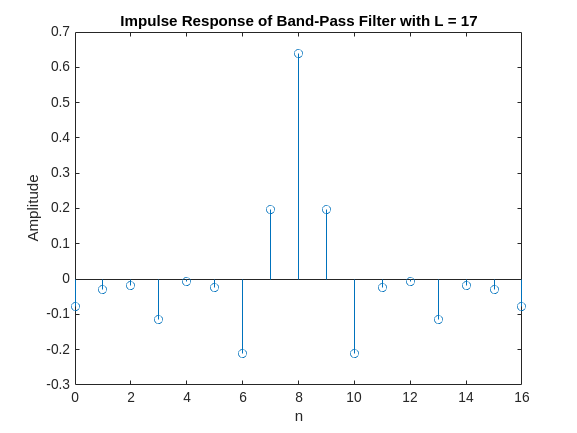

% Filter parameters
wa = 0.06 * pi;
wb = 0.7 * pi;

% Impulse response length
L = 17;
n = -(L-1)/2:(L-1)/2;

% Ideal impulse response
h_ideal = (sin(wb * n) - sin(wa * n)) ./ (pi * n);
h_ideal((L-1)/2 + 1) = (wb - wa) / pi; % handling division by zero at n = 0

% Make the impulse response causal
h_causal_L17 = circshift(h_ideal, [(L-1)/2, 0]);

% Plotting
figure;
stem(n + (L-1)/2, h_causal_L17);
title("Impulse Response of Band-Pass Filter with L = " + L);
xlim([0 L-1]);
xlabel('n');
ylabel('Amplitude');

#### 
$$L=33$$


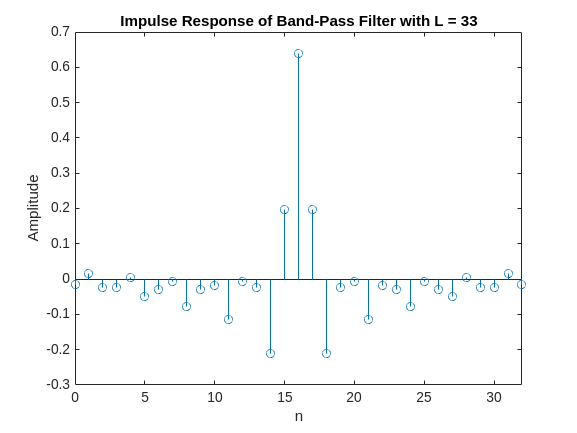

% Filter parameters
wa = 0.06 * pi;
wb = 0.7 * pi;

% Impulse response length
L = 33;
n = -(L-1)/2:(L-1)/2;

% Ideal impulse response
h_ideal = (sin(wb * n) - sin(wa * n)) ./ (pi * n);
h_ideal((L-1)/2 + 1) = (wb - wa) / pi; % handling division by zero at n = 0

% Make the impulse response causal
h_causal_L33 = circshift(h_ideal, [(L-1)/2, 0]);

% Plotting
figure;
stem(n + (L-1)/2, h_causal_L33);
title("Impulse Response of Band-Pass Filter with L = " + L);
xlim([0 L-1]);
xlabel('n');
ylabel('Amplitude');

#### 
$$L=65$$


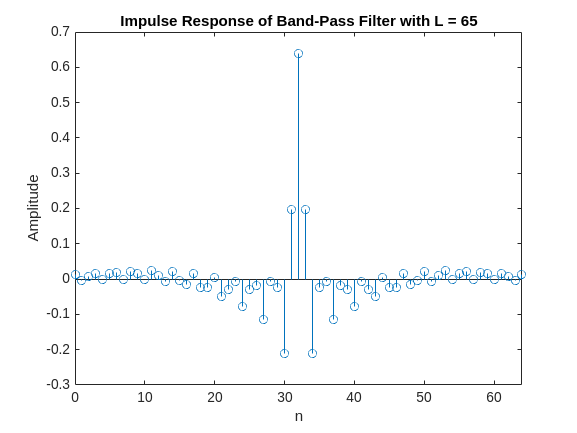

% Filter parameters
wa = 0.06 * pi;
wb = 0.7 * pi;

% Impulse response length
L = 65;
n = -(L-1)/2:(L-1)/2;

% Ideal impulse response
h_ideal = (sin(wb * n) - sin(wa * n)) ./ (pi * n);
h_ideal((L-1)/2 + 1) = (wb - wa) / pi; % handling division by zero at n = 0

% Make the impulse response causal
h_causal_L65 = circshift(h_ideal, [(L-1)/2, 0]);

% Plotting
figure;
stem(n + (L-1)/2, h_causal_L65);
title("Impulse Response of Band-Pass Filter with L = " + L);
xlabel('n');
xlim([0 L-1]);
ylabel('Amplitude');

### Step 2: Phase Delay

The number of samples in the filter between the start and the highest sample is given by $\frac{L-1}{2}$ . 


$$\text{Phase Delay}=\frac{L-1}{2}$$


#### 
$$L=17$$



$$=\frac{17-1}{2}=8  \text{ samples}$$


#### 
$$L=33$$



$$=\frac{33-1}{2}=16  \text{ samples}$$


#### 
$$L=65$$



$$=\frac{65-1}{2}=32  \text{ samples}$$


### Step 3: Magnitude Frequency Response

The dB-scale magnitude frequency response is plotted for each of the filters.

#### 
$$L=17$$


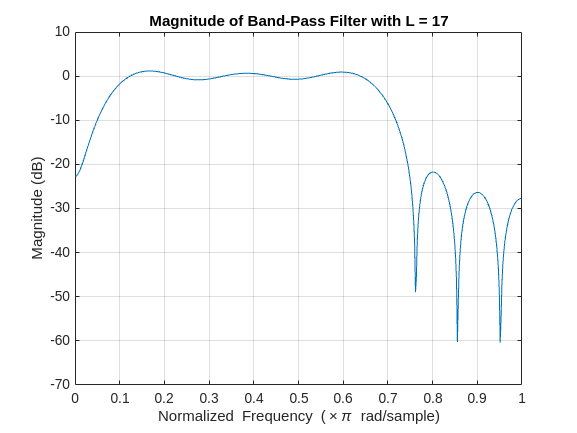

[h,w] = freqz(h_causal_L17);
plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of Band-Pass Filter with L = " + 17);
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

#### 
$$L=33$$


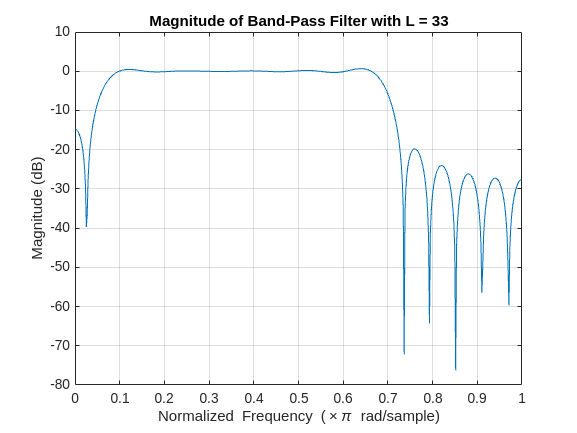

[h,w] = freqz(h_causal_L33);
plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of Band-Pass Filter with L = " + 33);
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

#### 
$$L=65$$


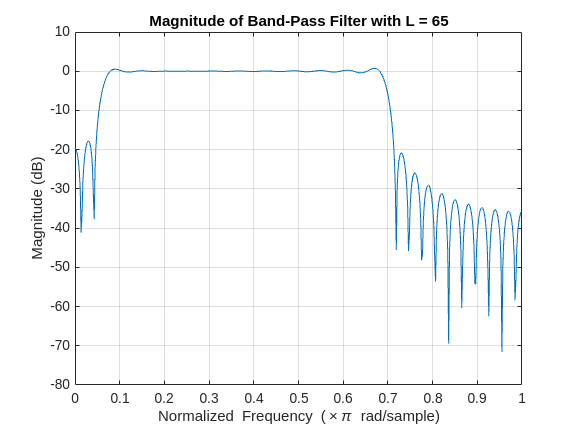

[h,w] = freqz(h_causal_L65);
plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of Band-Pass Filter with L = " + 65);
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

### Step 4: Filter Length

Filter length affects the magnitude frequency response of the filter by adding ripples. More specifically, the longer the filter length, the more ripples appear in the absolute magnitude before and after the bandpass frequency.

### Step 5: Filter with a Stop-Band Attenuation

To achieve a filter with a stop-band attenuation of $\delta_{stop}=0.003$ (amplitude ratio between stop-band maximum and pass-band maximum) and a transition band of ${\Delta}f=100\text{Hz}$ (frequency band length between the pass-band and the stop-band region) at a sample rate of $F_s = 48000 \text{Hz}$ different types of windows can be used. The features of the different windows are listed in the Appendix.

#### a) Value of the Stop-Band Attenuation in Power-dB Scale


$$\delta_{DB(stop)}=20log(0.003)=-50.46$$


#### b) Hann Window

The Hann window cannot be used to achieve such an attenuation because the the maximum stop-band should be -50dB and the Hann stop-band is at minimum -44dB. The windows that can achieve this attenuation are the Hamming and Blackman windows.

#### c) Required Transition Band

The lenght of an appropriate window that would allow to obtain the required transition band is computed below.


$${\Delta}f=\frac{C_\omega}{L_\omega}\rightarrow L_\omega=\frac{C_\omega}{\Delta f}$$


Fo the hamming window $C_\omega=3.3$:

 
$$\Delta f = 100 \rightarrow \Delta_{f0}=\frac{(2\pi)(100)}{48000}=\frac{\pi}{240}$$



$$L_\omega=\frac{C_\omega}{\Delta f}=\frac{(240)(3.3)}{\pi}=252.1$$


Need to round to 253 to obtain an uneven number.

#### d) Filtering Signal with the FIR 

*The filtered signal x using an FIR filter does correspond to what was expected because after 140 samples, the signal matches the targeted signal and the value is close to the phase delay that could be calculated using the formula from Step 2.*

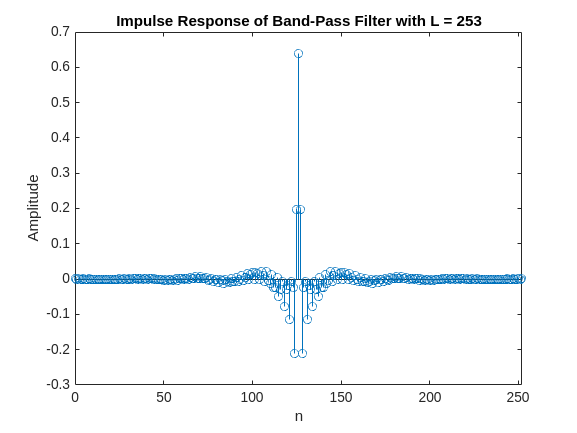

% Filter parameters
wa = 0.06 * pi;
wb = 0.7 * pi;

% Impulse response length
L = 253;
n = -(L-1)/2:(L-1)/2;

% Ideal impulse response
h_ideal = (sin(wb * n) - sin(wa * n)) ./ (pi * n);
h_ideal((L-1)/2 + 1) = (wb - wa) / pi; % handling division by zero at n = 0

% Make the impulse response causal
h_causal_hamming = circshift(hamming(L).'.*h_ideal, [(L-1)/2, 0]);

% Plotting
figure;
stem(n + (L-1)/2, h_causal_hamming);
title("Impulse Response of Band-Pass Filter with L = " + L);
xlabel('n');
xlim([0 L-1]);
ylabel('Amplitude');

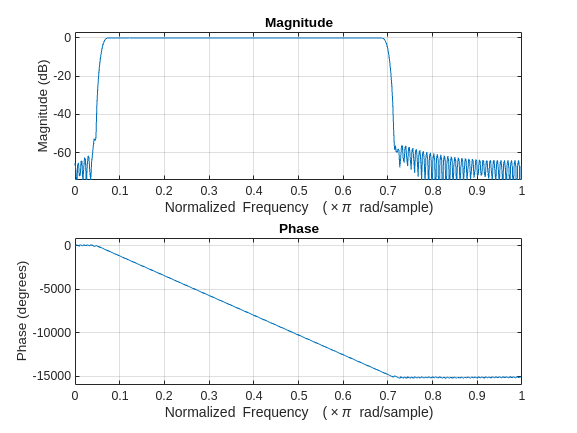

sample_size = 500;
N = 0:1:sample_size;

target = sin(2*pi*0.06*N)+(1/3)*sin(2*pi*0.18*N)+(1/5)*sin(2*pi*0.3*N);
noise = sin(2*pi*0.01*N)+(1/2)*sin(2*pi*0.4*N);
measured = target+noise;

filter_result = filter(h_causal_hamming,1,measured);
freqz(h_causal_hamming);

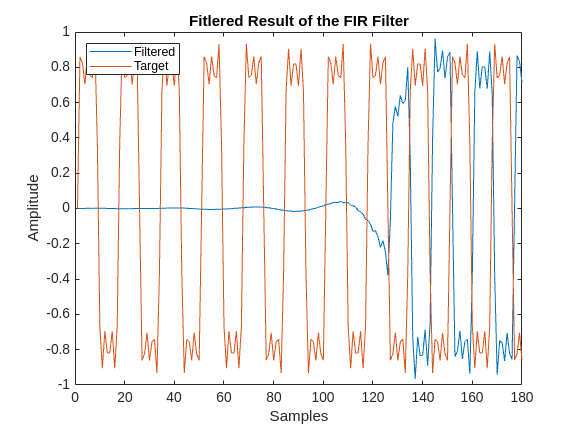


figure;
plot(filter_result);
title("Fitlered Result of the FIR Filter");
xlabel('Samples');
ylabel('Amplitude');
hold on;
plot(target);
xlim([0 180]);
hold off;
legend('Filtered', 'Target', 'Location','northwest');

**Sources used to complete this section:**

- [FIR Filter Properties - dspGuru](https://dspguru.com/dsp/faqs/fir/properties/)

## Part 3 - IIR Filter Design

### Step 1: Butterworth Band-Pass Filter

**A **$6^{th}$** order Butterworth band-pass filter is designed below with a pass-band starting at **$\omega_a=0.06\pi$** and ending at **$\omega_b=0.7\pi$**.**

wa = 0.06 * pi;
wb = 0.7 * pi;

wn = [wa wb] / (pi);

order = 6;
order = order/2; % bandpass needs to be divided by 2 to get the right order of the filter

[b,a] = butter(order,wn);

### Step 2: Impulse Response of Butterworth

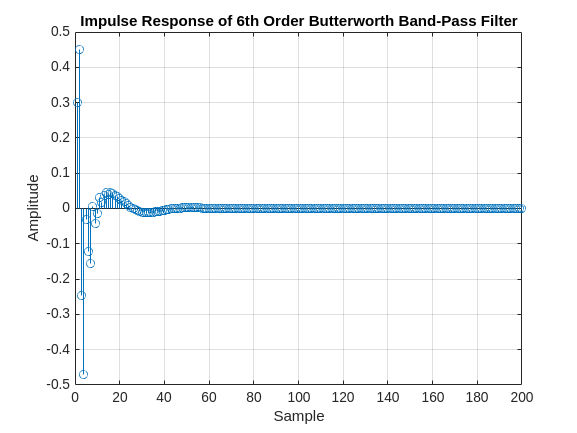

num_samples = 200;

impulse = [1 zeros(1, num_samples - 1)];

% Computing the impulse response of the filter
butter_filter = filter(b, a, impulse);

% Plotting the impulse response
stem(butter_filter);
title("Impulse Response of " + order*2 + "th Order Butterworth Band-Pass Filter");
xlabel('Sample');
ylabel('Amplitude');
grid on;

### Step 3: Butterworth Filter Difference from FIR Filter

The impulse response of the Butterworth filter is different from the FIR impulse responses found in Part 1, step 1 is that Instead of having the high impulse in the middle of the filter, it is close to the begining. Since the delay between the highest impulse and the start of the filter is shorter than the FIR filter, the phase delay should be smaller too.

### Step 4: Magnitude Frequency Response 

**The magnitude frequency response of this filter is plotted in dB. **

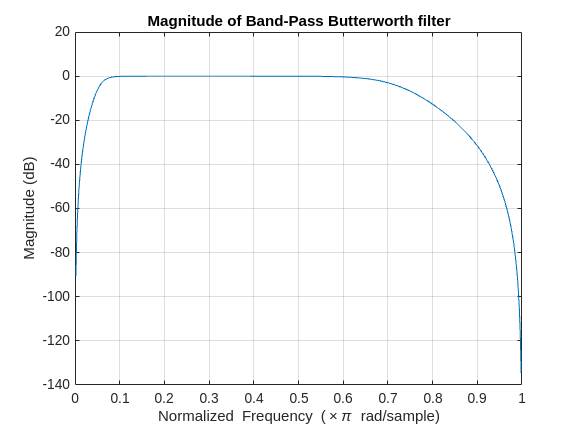

[h,w] =  freqz(b,a);
plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of Band-Pass Butterworth filter");
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

### Step 5: Cascading Combination of 3 Bi-Quad Filters

**The filter is re-implemented using a cascade combination of three ‘bi-quad’ filters below. Where each bi-quad has a transfer function of the form:**


$$H(z)=g\frac{1+b_1z^{-1}+b_2z^{-2}}{1+a_1z^{-1}+a_2z^{-2}}$$


**The command *****roots***** tis used o find the poles and the zeros of the Butterworth transfer function. Then the *****poly***** command can be used to group pairs of poles and zeros to form each bi-quad section. **

[z,p,k] = tf2zp(b,a);

g1 = k;
g2 = 1;
g3 = 1;

pair_z = cplxpair(z);
pair_p = cplxpair(p);
a_array = zeros([6 3]);
b_array = zeros([6 3]);

for i = 1:(length(pair_p)/2)
    a_array(i,:) = poly([pair_p(i*2) pair_p(i*2-1)]);
end
for i = 1:(length(pair_z)/2)
    b_array(i,:) = poly([pair_z(i*2) pair_z(i*2-1)]);
end

f1 = dsp.SOSFilter(g1*b_array(1,:), a_array(1,:));
tf(g1*b_array(1,:), a_array(1,:))

ans =
 
  0.3003 s^2 + 0.6005 s + 0.3003
  ------------------------------
     s^2 + 0.8321 s + 0.4503
 
Continuous-time transfer function.
Model Properties


f2 = dsp.SOSFilter(g2*b_array(2,:), a_array(2,:));
tf(g2*b_array(2,:), a_array(2,:))

ans =
 
      s^2 - 2 s + 1
  ----------------------
  s^2 - 1.803 s + 0.8373
 
Continuous-time transfer function.
Model Properties


f3 = dsp.SOSFilter(g3*b_array(3,:), a_array(3,:));
tf(g3*b_array(3,:), a_array(3,:))

ans =
 
   s^2 + 3.817e-08 s - 1
  -----------------------
  s^2 - 0.5335 s - 0.2235
 
Continuous-time transfer function.
Model Properties


### Step 6: Magnitude Frequency Response of Each Bi-Quad Section

**The dB-scale magnitude frequency response of each bi-quad section is plotted below.**

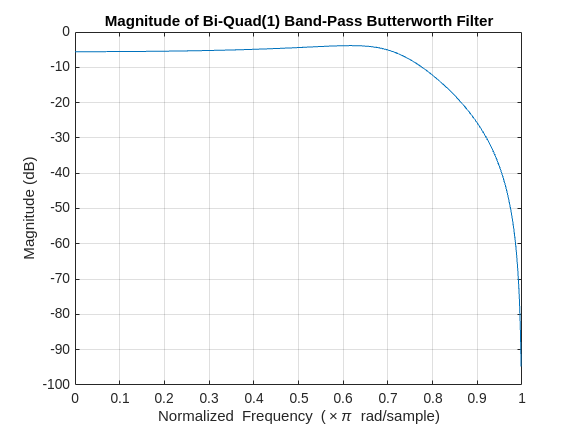

[h,w] =  freqz(g1*b_array(1,:),a_array(1,:));
plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of Bi-Quad(1) Band-Pass Butterworth Filter");
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

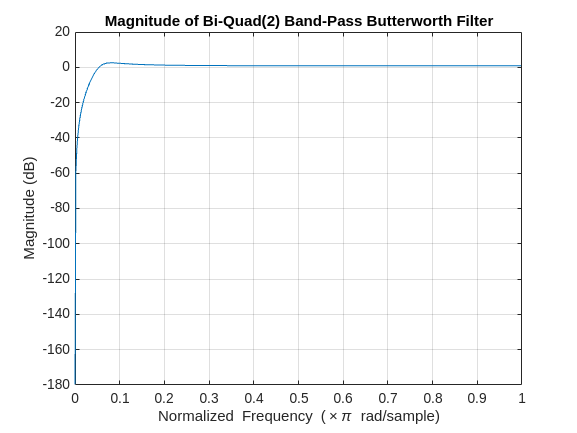

[h,w] = freqz(g2*b_array(2,:),a_array(2,:));
plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of Bi-Quad(2) Band-Pass Butterworth Filter");
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

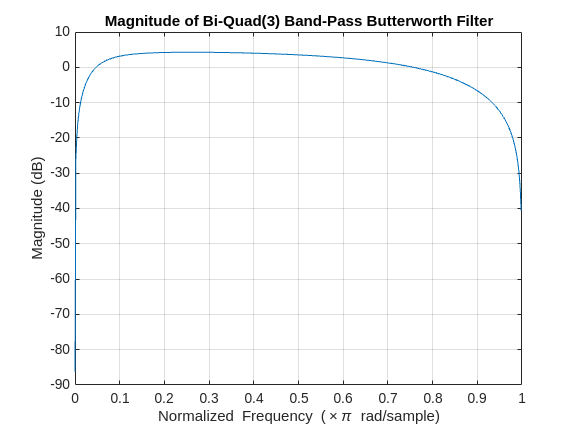

[h,w] = freqz(g3*b_array(3,:),a_array(3,:));
plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of Bi-Quad(3) Band-Pass Butterworth Filter");
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

### Step 7: Magnitude Frequence Response of the Cascade Combination of Three Bi-Quad Sections

**The dB-scale magnitude frequency response of the cascade combination of the three bi-quad sections is plotted below. **

*The dB-scale magnitude frequency response of the cascade combination fo the three bi-quad sections are the same as the plots generated in Part 3, Step 4 as they have the same cutoff frequencies and they have a flat bandpass.*

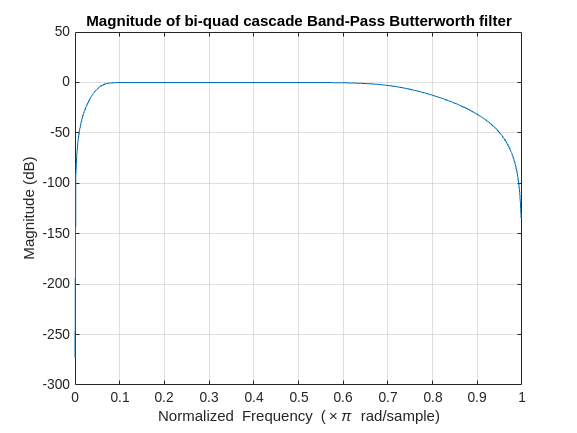

[h,w] = freqz(conv(conv(g1*b_array(1,:),g2*b_array(2,:)),g3*b_array(3,:)),conv(conv(a_array(1,:),a_array(2,:)),a_array(3,:)));

plot(w/pi,20*log10(abs(h)));
grid on;
title("Magnitude of bi-quad cascade Band-Pass Butterworth filter");
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

### Step 8: Filtering Signal with the Cascading Butterworth Filter

*The signal is filtered by the Butterworth filter designed in Part 3, Step 1. The output is not is not comparable to what was obtained in Part 2, Step 5d) because the phase delay is shorter but the quality of the signal is worse. However, the two filters have the same frequency as the targeted signal.*

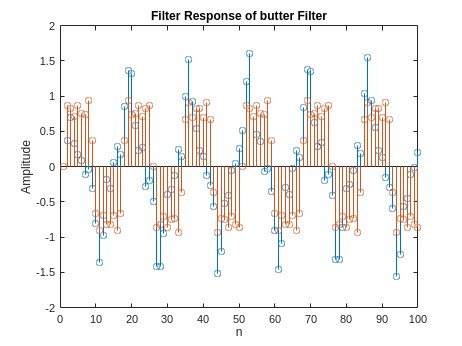

y1 = filter(g1 * b_array(1,:),a_array(1,:),measured);
y2 = filter(g2 * b_array(2,:),a_array(2,:),y1);
y3 = filter(g3 * b_array(3,:),a_array(3,:),y2);

figure;
stem(y3);
title("Filter Response of butter Filter");
xlabel('n');
xlim([0 100]);
ylabel('Amplitude');
hold on;
stem(target);
hold off;

### Step 9: Phase Response of the Butterworth Filter

**The phase response of the Butterworth filter is plotted below. **

*Based on the shape of the phase response, the phase response seems to have an almost linear shape without a plateau versus the phase response of Part 2, Step5d) also has a linear shape to begin with but plateaus at the cutoff frequency. The behavior would explain why the signal is not as clean with the IIR filter compared to the FIR filter.*

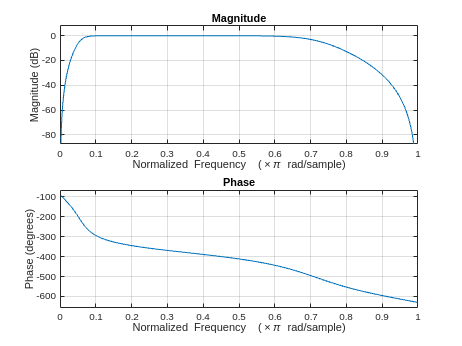

freqz(conv(conv(g1*b_array(1,:),b_array(2,:)),b_array(3,:)),conv(conv(a_array(1,:),a_array(2,:)),a_array(3,:)))

**Sources used to complete this section:**

- [https://youtu.be/_lwR1cvF4Io?si=6bjp1BiDEl6ZhTrA](https://youtu.be/_lwR1cvF4Io?si=6bjp1BiDEl6ZhTrA)

## Appendix - Characteristics for Standard Windows

The stop-band attenuation of a window is the attenuation in power-dB, between the maximum of the Fourier transform of the window and the highest value of its stop-band region, i.e. outside of its main lobe. The width $\triangle f$ of the transition-band region is inversely proportional to the length $L_\omega$ of the window, *i.e:*


$$\triangle f = \frac{C_\omega}{L_\omega}$$


where $C_\omega$ is the constant that depends on the window (see the table below).